clear all; clc;
Nt=10; Nx=10; T=1; X=2; beta=1.25;
n=1000;
thetaCold=ColdStart(Nt,Nx,T,X);
% avg1 = avgPlaquette(theta,T,X);
% Plaqt = PlaquetteTest(theta,T,X);
% argu=thetahot(1,1,T)+thetahot(2,1,X)-thetahot(1,2,T)-thetahot(1,1,X);
% p1=exp(1i*argu)
% S_action=Action(theta,beta);
% arg1=Plaqt(1,1)+Plaqt(2,1)+Plaqt(1,2)+Plaqt(2,2);
% S_action1=beta*real(4-arg1);
% MetrplsC=MetropolisSweep(thetaCold,beta);
% N=length(MetrplsC);

ActionC=zeros(1,n);
avgPC=zeros(1,n);

for k=1:n
    thetaC=MetropolisSweep(thetaCold,beta);
    ActionC(k)=Action(thetaC,beta);
    avgPC(k)=avgPlaquette(thetaC,T,X);
end
mnAC=mean(ActionC)

mnAC = 30.1250

errAC=std(ActionC)

errAC = 4.7824

mnavgPC=mean(avgPC)

mnavgPC = 0.7590 + 0.0011i

erravgPC=std(avgPC)

erravgPC = 0.0443

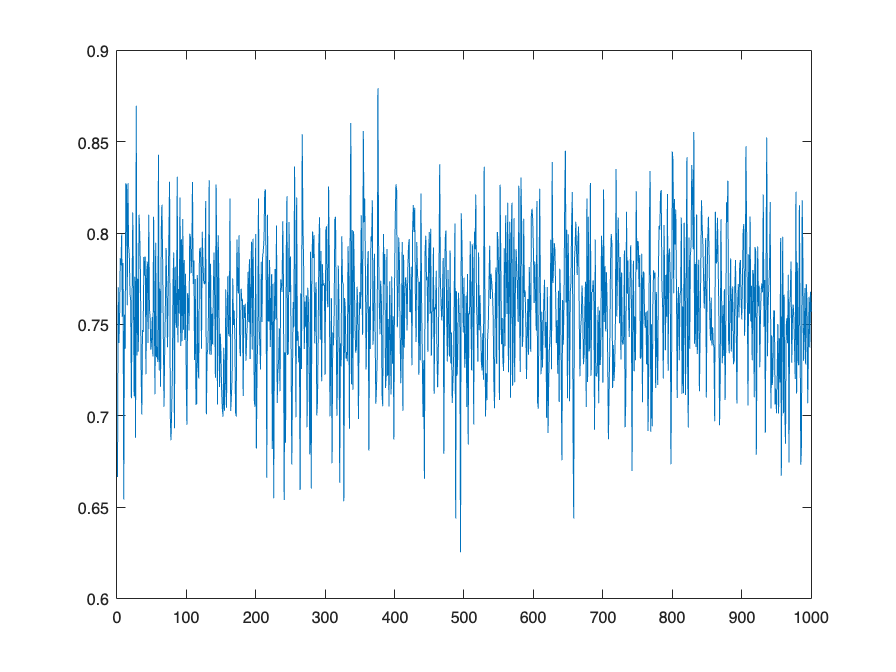

plot(1:n,avgPC)

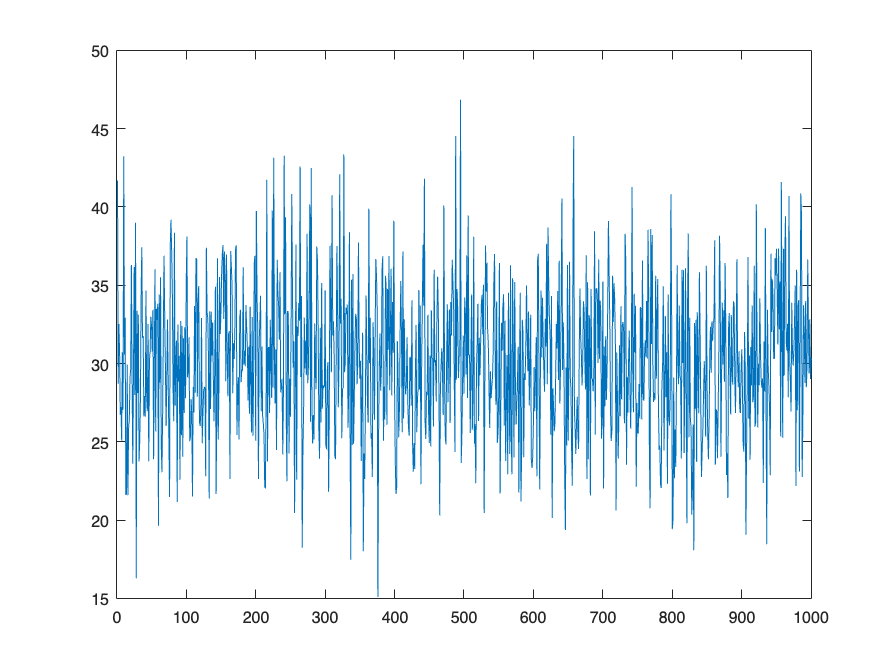

plot(1:n,ActionC)

thetaHot=HotStart(Nt,Nx,T,X);

ActionH=zeros(1,n);
avgPH=zeros(1,n);

for k=1:n
    thetaH=MetropolisSweep(thetaHot,beta);
    ActionH(k)=Action(thetaH,beta);
    avgPH(k)=avgPlaquette(thetaH,T,X);
end
mnAH=mean(ActionH)

mnAH = 89.8980

errAH=std(ActionH)

errAH = 6.8962

mnavgPH=mean(avgPH)

mnavgPH = 0.2808 - 0.0004i

erravgPH=std(avgPH)

erravgPH = 0.0857